**Skills 10: Photosynthesis and Group Dynamics**

**23.)**

**Given**

Delaware River depth and light intensity data:

ddel = [0, 1, 2, 3, 4, 5, 6, 7]; %depth in ft
Idel = [100, 42, 18.5, 11.5, 5.1, 2.0, 0.73, 0.27]; %Relative light intensity

Lake Tahoe depth and light intensity data:

dtah = [0, 33, 60, 100, 200]; %depth in ft
Itah = [100, 30, 18, 9, 2]; %Relative light intensity

**Required**

- Plot the data as a function of depth

- Estimate the extinction coefficients, $K_e$ (to base e) in 1/ft for both sets of data. Also estimate the depth at which 1% of the surface light still exists.

**Sketch**

**Theory**

- I will plot the light intensity data as a function of depth using a simple line graph. I will then estimate $K_e$ using Beer's Law.

Beer's Law: $\ln E_Z =\ln E_0 -K_e Z\longrightarrow K_e =\frac{\ln E_Z -\ln E_0 }{-Z}$

- I will estimate the depth at which 1% of the surface light still exists through linear regression of the line of lnE vs depth. 

**Assumptions**

- I assume that light intensity will eventually equal zero at some point.

- I assume that the E variable in Beer's law = light intensity.

**Solution**

- First, I plotted light intensity vs depth:

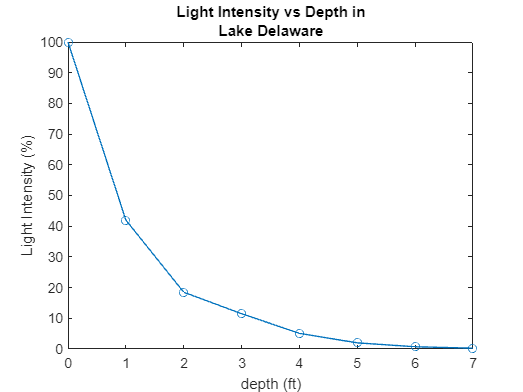

figure
plot(ddel,Idel,'o-')

title(["Light Intensity vs Depth in", "Lake Delaware"])
ylabel("Light Intensity (%)")
xlabel("depth (ft)")

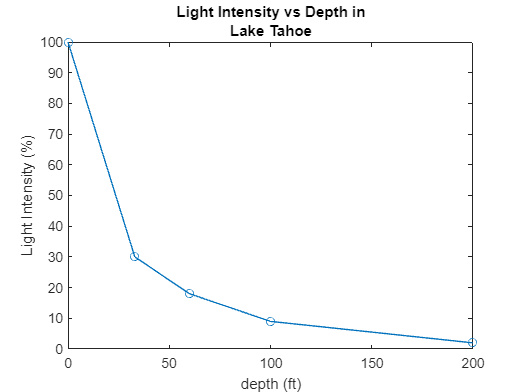

figure
plot(dtah,Itah,'o-')

title(["Light Intensity vs Depth in", "Lake Tahoe"])
ylabel("Light Intensity (%)")
xlabel("depth (ft)")

- I then used Beer's Law to estimate $K_e$ at 4 ft in Lake Delaware and 100 ft in Lake Tahoe:

Lake Delaware: $K_e =\frac{\ln E_Z -\ln E_0 }{-Z}$ = $\frac{\ln 5\ldotp 1-\textrm{ln100}}{-5\ldotp 1}=0\ldotp 58\;{\textrm{ft}}^{-1}$

Lake Tahoe: $K_e =\frac{\ln E_Z -\ln E_0 }{-Z}$ = $\frac{\textrm{ln9}-\textrm{ln100}}{-100}=0\ldotp 024\;{\textrm{ft}}^{-1}$

- I then estimated the depth at which 1% of surface light exists in each lake ($E_Z =1%$) using the Beer's Law equation to solve for Z.

Lake Delaware: $Z=\frac{\ln E_Z -\ln E_0 }{-K_e }=\frac{\ln 1-\textrm{ln100}}{-0\ldotp 58}=7\ldotp 94\;\textrm{ft}$

Lake Tahoe: $Z=\frac{\ln E_Z -\ln E_0 }{-K_e }=\frac{\ln 1-\textrm{ln100}}{-0\ldotp 024}=192\ldotp 9\;\textrm{ft}$

**Discussion**

The calculated values at which 1% of light still exists do not match perfectly with the data, but the relationship is still pretty close. From looking at the data, Lake Tahoe obviously is a much clearer lake with much less turbidity than Lake Delaware and is likely among other factors a reason why Lake Tahoe is a world-renowed vacation destination and Lake Delaware's Wikipedia article is only 1 sentence.

.........................................................................................................................................................................................

**24.)**

**Given**

- 
$$T=10\;C$$


- 
$$f=0\ldotp 6$$


- 
$$I_S =350\;\textrm{ly}/\textrm{day}$$


- 
$$K_e =0\ldotp 5/m$$


- 
$$G_{\max } =1\ldotp 8/\textrm{day}$$


- 
$$I_T =500\;\textrm{ly}/\textrm{day}$$


- 
$$K_{\textrm{mp}} =2\;\mu g\;P/L$$


- 
$$\mu_R =0\ldotp 15/\textrm{day}$$


- 
$$H=17\;m$$


**Required**

- If nutrients are not limiting, what are the growth, death (no zooplankton), and net growth rates of the phytoplankton assuming no settling? If the initial phytoplankton chlorolphyll at t=0 is $1\ldotp 0\;\mu g/L$, what would the phytoplankton level be if this net growth rate persisted for 30 days?

- Plot the relationship of growth rate vs available P concentration.

- Repeat part 1 if the ambient available P concentration is $2\;\mu g\;P/L$.

**Sketch**

**Theory**

- I plan to use Michaelis-Menten kinetics to solve this problem using P as the limiting nutrient for part 3.

**Assumptions**

- 
$$G_{\max } =\mu_{\max }$$


- No settling

- Net growth rate = growth rate - death rate

**Solution**

1.) 

- Growth rate: $\nu =\frac{\mu_{\max } }{K_S +S}=\frac{1\ldotp 8/\mathrm{day}*1\ldotp 0\;\mu g/L}{2\mu g/L+1\ldotp 0\;\mu g/L}=0\ldotp 6/\mathrm{day}$

- Death rate: $\nu_d =\left(1-f\right)*\nu =0\ldotp 4*0\ldotp 6/\mathrm{day}=0\ldotp 24/\mathrm{day}$

- Net growth rate: $\nu_{\mathrm{net}} =\nu -\nu_d =0\ldotp 6/\mathrm{day}-0\ldotp 24/\mathrm{day}=0\ldotp 36/\mathrm{day}$

- Net growth after 30 days: $\nu_{\mathrm{net30}} =S*\nu_{\mathrm{net}} *30\;d=0\ldotp 36/\mathrm{day}*1\ldotp 0\;\mu g/L*\;30\;d=10\ldotp 8\;\mu g/L$ 

2.)

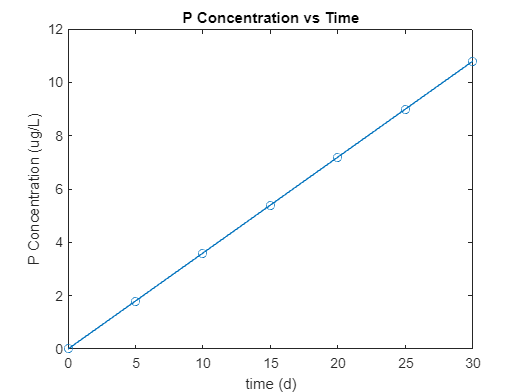

t = [0, 5, 10, 15, 20, 25, 30]; %time in days
P = 1*0.36*t;

figure
plot(t,P,'o-')

title(["P Concentration vs Time"])
ylabel("P Concentration (ug/L)")
xlabel("time (d)")

3.)

Ambient P concentration = $2\ldotp 0\;\mu g/L$

- Growth rate: $\nu =\frac{\mu_{\max } }{K_S +S}=\frac{1\ldotp 8/\mathrm{day}*1\ldotp 0\mu g/L*\;2\ldotp 0\;\mu g/L}{2\mu g/L+1\ldotp 0\;\mu g/L}=1\ldotp 2/\mathrm{day}$

- Death rate: $\nu_d =\left(1-f\right)*\nu =0\ldotp 4*0\ldotp 9/\mathrm{day}=0\ldotp 48/\mathrm{day}$

- Net growth rate: $\nu_{\mathrm{net}} =\nu -\nu_d =1\ldotp 2/\mathrm{day}-0\ldotp 48/\mathrm{day}=0\ldotp 72/\mathrm{day}$

- Net growth after 30 days: $\nu_{\mathrm{net30}} =S*\nu_{\mathrm{net}} *30\;d=0\ldotp 72/\mathrm{day}*1\ldotp 0\;\mu g/L*\;30\;d=21\ldotp 6\;\mu g/L$

**Discussion**

The ambient P concentration appears to have a large effect on growth rate. When it was increased to $2\ldotp 0\;\mu g/L$, the net growth after 30 days more than doubled. 